% PB
%P2
point = [0 pi / 4 pi / 2 3 * pi / 2];
nodevals = sin(point);

t = -pi : 0.01 : pi;
hermite_results = Hermite_multiplePoints(point, nodevals, nodevals, t);

fprintf("Reprezentarea grafică a sin(x) și a polinomului său de interpolare Hermite:");

Reprezentarea grafică a sin(x) și a polinomului său de interpolare Hermite:

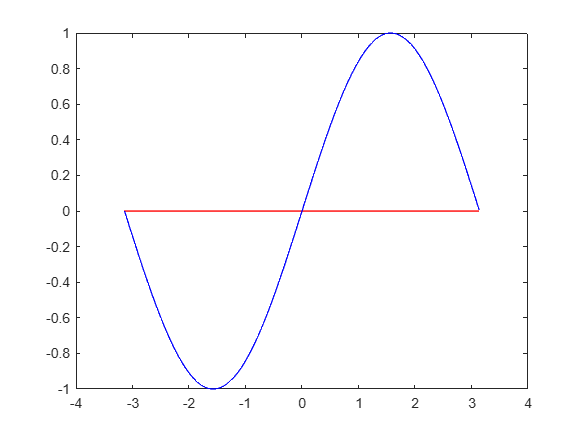

plot(t, hermite_results, 'red');
hold on;
results = sin(t);
plot(t, results, 'blue');
hold off;



%P3
% Fie f: [-2, 2] -> R, f(x) = x^2
x = [-2 2];
f = [4 4]; 
fderiv = [-4 4];

t = -2 : 0.01 : 2;
results = Hermite_multiplePoints(x, f, fderiv, t);

fprintf("Reprezentarea grafică a unei cubice parametrice Hermite (x^2):")

Reprezentarea grafică a unei cubice parametrice Hermite (x^2):

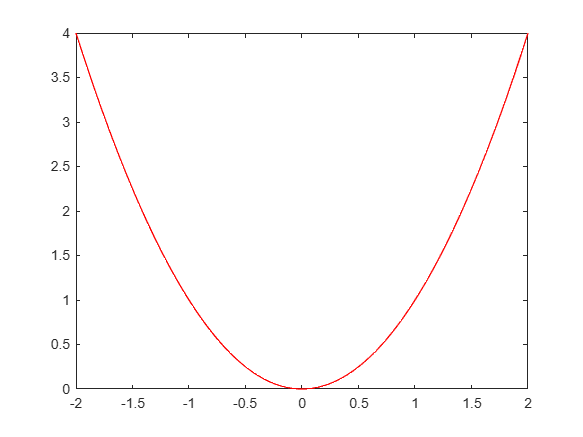

plot(t, results, 'red');



% PB PRACTICE
%P1
x = 0.25;
fprintf("Hermite: exp(%f) = %f", x, Hermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], x));

Hermite: exp(0.250000) = 1.250000

fprintf("Software: exp(%f) = %f", x, exp(x));

Software: exp(0.250000) = 1.284025



%P2
x = [0.3, 0.32, 0.35];
f = sin(x);
fderiv = cos(x);
point = [0.34];

h = Hermite(x, f, fderiv, point);
fprintf("PRIMA APROXIMARE:");

PRIMA APROXIMARE:

fprintf("Hermite: sin(%f) = %f", point, h);

Hermite: sin(0.340000) = 0.333734

fprintf("Software: sin(%f) = %f", point, sin(point));

Software: sin(0.340000) = 0.333487

fprintf("EROARE: %f", abs(sin(point) - h));

EROARE: 0.000247


% Adăugăm punctul 0.33 la datele noastre:
x = [0.3, 0.32, 0.33, 0.35];
f = sin(x);
fderiv = cos(x);
point = [0.34];

h = Hermite(x, f, fderiv, point);
fprintf("A DOUA APROXIMARE:");

A DOUA APROXIMARE:

fprintf("Hermite: sin(%f) = %f", point, h);

Hermite: sin(0.340000) = 0.333734

fprintf("Software: sin(%f) = %f", point, sin(point));

Software: sin(0.340000) = 0.333487

fprintf("EROARE: %f", abs(sin(point) - h));

EROARE: 0.000247



%P3
timpi = [0, 3, 5, 8, 13];
distante = [0, 225, 383, 623, 993];
viteze = [75, 77, 80, 74, 72];
noduri = [10];

[d, dH] = Hermite_withDerivative(timpi, timpi, viteze, noduri);
fprintf("La momentul t = 10, avem:");

La momentul t = 10, avem:

fprintf("Distanța: %f", d);

Distanța: 2208.362426

fprintf("Viteza: %f", dH);

Viteza: 2136.780893

function [result] = Hermite(x, f, fderiv, point)

    [~, m] = size(x);
    Q = zeros(2 * m + 2, 2 * m + 2);
    z = zeros(2 * m + 2);
    
    for i = 1 : m
        z(2 * i - 1) = x(i);
        z(2 * i) = x(i);
        Q(2 * i - 1, 1) = f(i);
        Q(2 * i, 1) = f(i);
        Q(2 * i, 2) = fderiv(i);

        if (i ~= 1)
            Q(2 * i - 1, 2) = (Q(2 * i - 1, 1) - Q(2 * i - 2, 1)) / (z(2 * i - 1) - z(2 * i - 2));
        end
    end
    
    for i = 3 : 2 * m
       for j = 3 : i
          Q(i, j) = (Q(i, j - 1) - Q(i - 1, j - 1)) / (z(i) - z(i - j + 1)); 
       end
    end
    
    s = 1;
    p = Q(1, 1);
    for i = 2 : 2 * m
       a = abs(x(floor(i / 2)) - point);
       s = s * a;
       prev = p;
       p = p + s * Q(i, i);
       result = p;
       if (prev - p < 1E-5)
          break 
       end
    end

end

function [results] = Hermite_multiplePoints(x, f, fderiv, points)
    results = zeros(size(points));
    for i = 1 : length(points)
        results(i) = Hermite(x, f, fderiv, points(i)); 
    end
end

function T = dif_div_duble(x, f, df)

	T = NaN(2 * length(x));
	z = repelem(x, 2);
	T(:, 1) = repelem(f, 2);
	T(1 : 2 : end - 1, 2) = df;
	T(2 : 2 : end - 2, 2) = diff(f) ./ diff(x);
	for j = 3 : length(z)
		 T(1 : end - j + 1, j) = diff(T(1 : end - j + 2, j - 1)) ./ (z(j : end) - z(1 : end - j + 1))';
    end

end

function [H, dH] = Hermite_withDerivative(x, f, fderiv, X)
	
    coefs = dif_div_duble(x, f, fderiv);
    coefs = coefs(1, :);
    
	z = repelem(x, 2);
	H = X; 
	dH = X;
    for k = 1 : length(X)
        P = 1; DP = 0; 
        H(k) = coefs(1) * P;
        dH(k) = 0;

        for i = 2 : length(coefs)
            DP = DP * (X(k) - z(i - 1)) + P;
            P = P * (X(k) - z(i - 1));
            H(k) = H(k) + coefs(i) * P;
            dH(k) = dH(k) + coefs(i) * DP;
        end
    
    end

end
